# **Kelly Criterion**

% Define the variables
p = 0.6; % Probability of winning
q = 1 - p; % Probability of losing
b = 2; % Odds received on the bet

% Calculate the Kelly fraction
f_star = (b * p - q) / b;

% Display the result
disp(['Optimal fraction of bankroll to bet (Kelly Criterion): ', num2str(f_star)]);

Optimal fraction of bankroll to bet (Kelly Criterion): 0.4


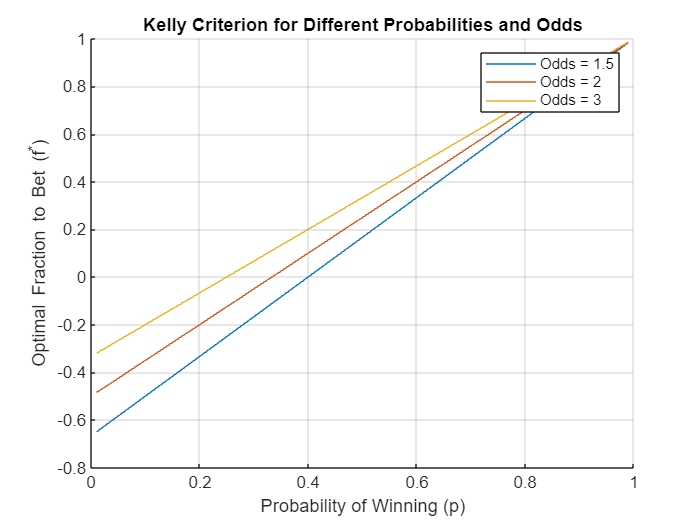


% Visualization for different probabilities and odds
p_values = linspace(0.01, 0.99, 100);
b_values = [1.5, 2, 3];

figure;
hold on;
for i = 1:length(b_values)
    b = b_values(i);
    f_star_values = (b .* p_values - (1 - p_values)) ./ b;
    plot(p_values, f_star_values, 'DisplayName', ['Odds = ', num2str(b)]);
end
xlabel('Probability of Winning (p)');
ylabel('Optimal Fraction to Bet (f^*)');
title('Kelly Criterion for Different Probabilities and Odds');
legend show;
grid on;